# **ETSMP - TRANSFORMATIONS & MULTIVARIATE RANDOM VARIABLES**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **PROBLEM 2.32**

**Let **$Z=X+Y-c$**, where X and Y are independent random variables with variances **$\sigma_x^2$, $\sigma_y^2$ **and **$c$** is constant. Find the variance of Z in terms of **$\sigma_x^2$, $\sigma_y^2$ **and **$c$. 

## SOLUTION 

# **PROBLEM 2.35**

$X$ **is a Gaussian random variable with mean **$0$ **and variance **$\sigma_x^2$. **Find the pdf of Y if**

**A: **$Y=X^2$

**B: **$Y=|X|$

## SOLUTION

# **DATA SAMPLING**

**You need test data (virtual measurements) for test or simulation of a flight simlulator. The testdata should simulate the altitude of a plane and are supposed to be Rayleigh distributed.**


$$f_x \left(x\right)=\frac{x}{\sigma^2 }\cdot e^{-\frac{x^2 }{2\sigma^2 }}$$


## RAYLEIGH DISTRIBUTION

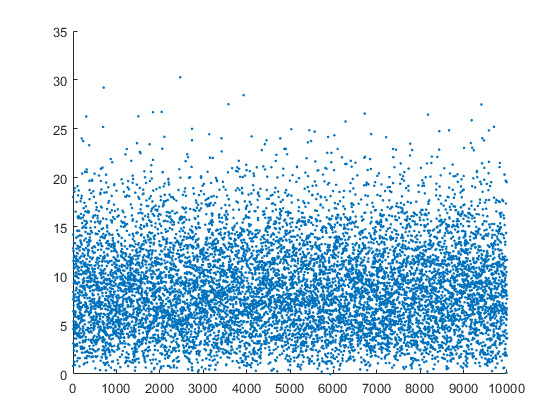

dataPoints = 10000;
sigma = 7;

x = sqrt(-2.*sigma^2.*log(1 - rand(dataPoints, 1)));

figure(1)
scatter(1:dataPoints, x, '.');

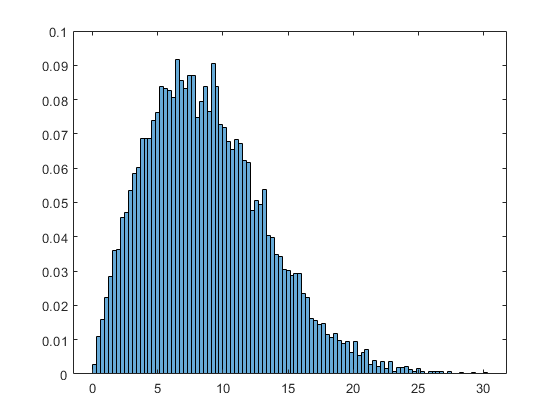


figure(2)
smp.pdfhist(x, 100);

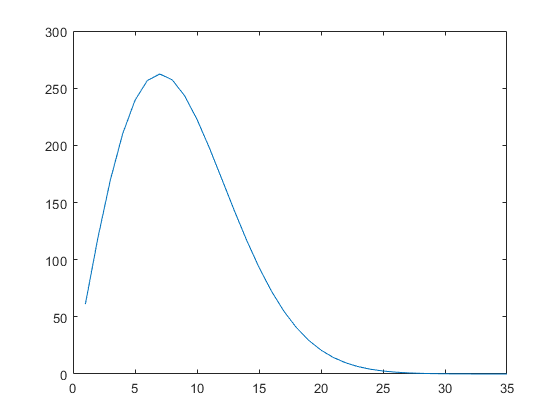


rayleigh = 0:1:1000;
for i = 1:1000
    rayleigh(i) = dataPoints*max(x)/100*i./sigma^2.*exp(-i^2./(2*sigma^2.));
end

figure(3)
plot(1:35, rayleigh(1:35))

## EXPONENTIAL DATA

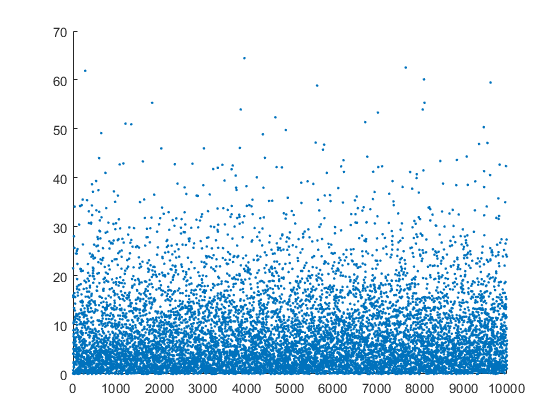

dataPoints = 10000;
lambda = 1/8;

x = -1/lambda.*log(1-rand(dataPoints, 1));

figure(4)
scatter(1:dataPoints, x, '.');

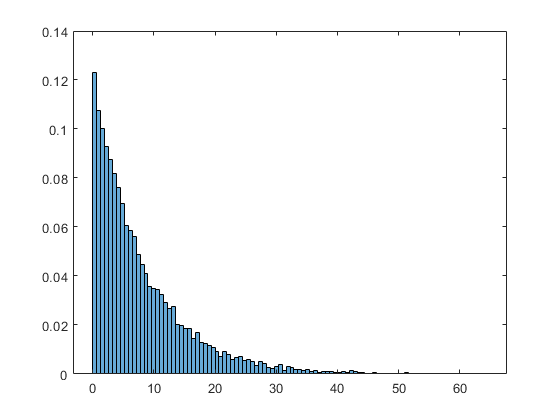


figure(5)
smp.pdfhist(x, 100);

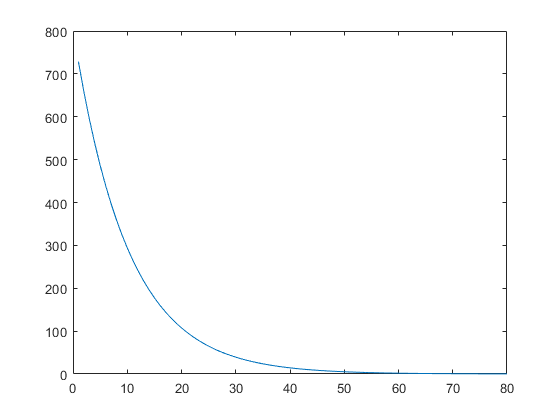


exponential = 0:1:80;

for i = 1:80
    exponential(i) = dataPoints*max(x)/100*lambda.*exp(-i*max(x)/80.*lambda);
end

figure(6)
plot(1:80, exponential(1:80))